# Homework #1

ME599 Data Analysis

Aaron Cornelius

2020-8-26

### 1. Determine the period of the function defined by $x\left(t\right)=\mathrm{sin}\;11t+\mathrm{sin}\;12t$ 

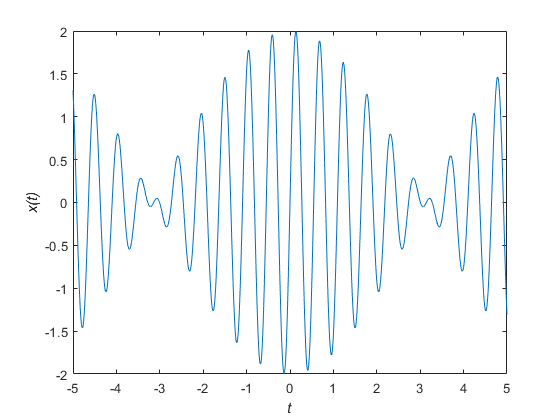

f = @(t) sin(11*t) + sin(12*t);
figure
fplot(f, [-5 5])
xlabel('\it{t}')
ylabel('\it{x(t)}')

There are two main methods of finding the period of this function. Both will be demonstrated. First, we can find the highest common frequency divisor for the two frequencies $\frac{11}{2\pi \;},\frac{12}{2\pi \;}$, and then calculate the period of that frequency. The standard Matlab code `gcd` for finding the greatest common factor only works on integers, so the $\frac{1}{2\pi \;}$ will be factored out. Once that is calculated, the frequency will be inverted to find the period (truncated here to three significant digits.)

f_common = 1/(2*pi) * gcd(11, 12);
disp(['The period of this function is: ' num2str(1/f_common, 3)])

The period of this function is: 6.28


This agrees with visual inspection of the graph. The other main method is to find the least common multiple of the periods $\frac{2\pi \;}{11},\frac{2\pi \;}{12}$. This can be done with Matlab's `lcm` function on a symbolic array of the . This method is generally more robust, since it can be performed on an arbitrary number of non-integer inputs using a symbolic array.

calcPeriod = @(periods) lcm(sym(periods));
period = calcPeriod([2*pi/11, 2*pi/12])

$$period = 2\,\pi$$

Since $2\pi$ is equivelent to `6.28` to three significant figures, both methods found the same answer. This is the method that will be used going forward.

### 2. For the following functions, which are periodic and which are non-periodic?

#### (a) $x\left(t\right)=3\;\mathrm{sin}\;t+2\;\mathrm{sin}\;2t+\mathrm{sin}\;3t$

This function is periodic, since all three ratios of the angular velocities are rational: $\frac{1}{2},\frac{1}{3},\frac{2}{3}$.

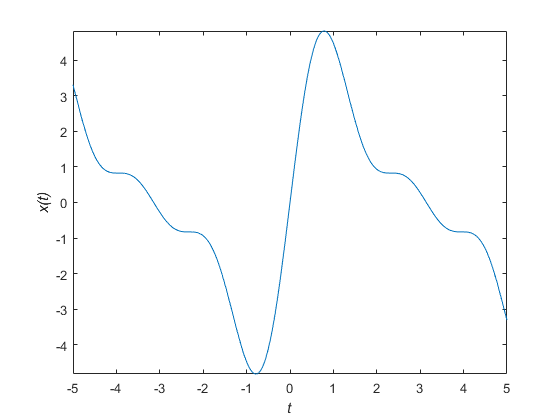

f = @(t)3*sin(t) + 2*sin(2*t)+sin(3*t);
figure
fplot(f, [-5, 5])
xlabel('\it{t}')
ylabel('\it{x(t)}')

The period is calculated as the least common multiple of the periods of each of the subfunctions: $2\pi \;,\frac{2\pi \;}{2},\frac{2\pi \;}{3}$.

period = calcPeriod([2*pi, 2*pi/2, 2*pi/3])

$$period = 2\,\pi$$

#### (b) $x\left(t\right)=3\;\mathrm{sin}\;t+2\;\mathrm{sin}\;2t+\mathrm{sin}\;\pi t$

This function is not periodic. This can be seen by calculating the ratio of either the first or second term's angular velocity to the third term's angular velocity: $\frac{1}{\pi \;}$ or $\frac{2}{\pi \;}$. These ratios are not rational, and therefore the function is not periodic.

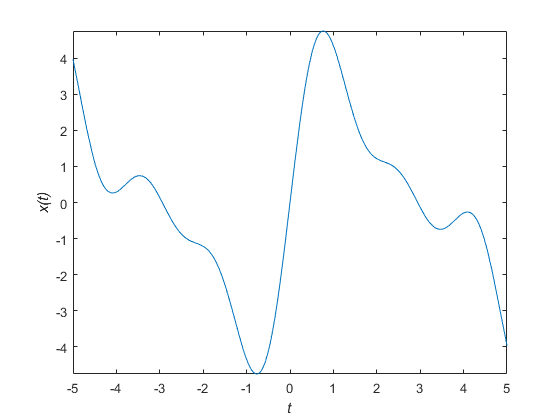

f = @(t)3*sin(t) + 2*sin(2*t)+sin(pi*t);
figure
fplot(f, [-5, 5])
xlabel('\it{t}')
ylabel('\it{x(t)}')

#### (c) $x\left(t\right)=3\;\mathrm{sin}\;4t+2\;\mathrm{sin}\;5t+\mathrm{sin}\;6t$

This function is periodic. All the ratios between the different angular velocities are rational: $\frac{4}{5},\frac{4}{6},\frac{5}{6}$. 

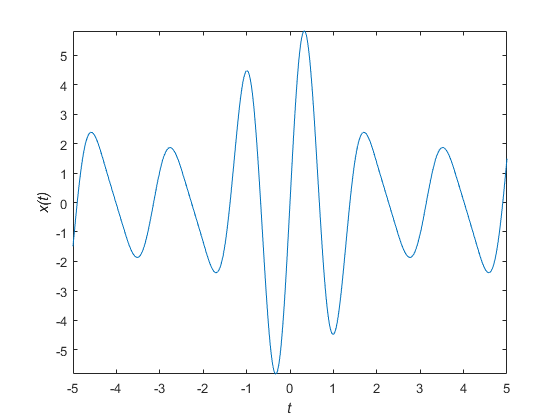

f = @(t)3*sin(4*t) + 2*sin(5*t)+sin(6*t);
figure
fplot(f, [-5, 5])
xlabel('\it{t}')
ylabel('\it{x(t)}')

The period is calculated as the least common multiple of the periods of each of the subfunctions: $\frac{2\pi }{4}\;,\frac{2\pi \;}{5},\frac{2\pi \;}{6}$.

period = calcPeriod([2*pi/4, 2*pi/5, 2*pi/6])

$$period = 2\,\pi$$

#### (d) $x\left(t\right)=e^{-t} \;\mathrm{sin}\;t$

This function is not periodic due to the exponential term, which will never repeat, and instead decays exponentially.

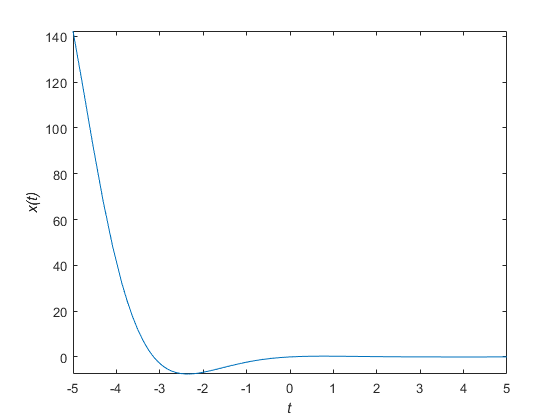

f = @(t)exp(-t).*sin(t);
figure
fplot(f, [-5, 5])
xlabel('\it{t}')
ylabel('\it{x(t)}')

### 3. Determine if $x\left(t\right)=\mathrm{sin}\left(\sqrt{50}t\right)+4\;\mathrm{cos}\left(\sqrt{\;98}t-\frac{\;\pi \;}{4}\right)$is periodic, and if so, what is its period?

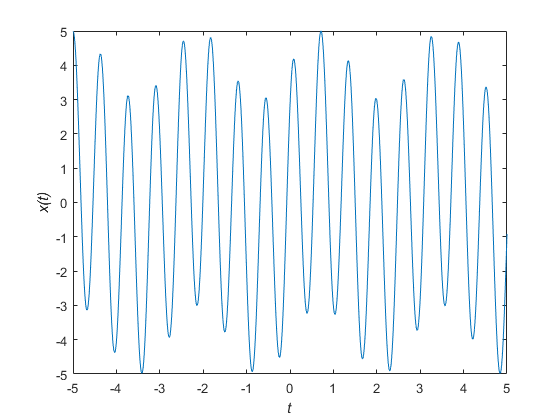

f = @(t)sin(sqrt(5)*t)+4*cos(sqrt(98)*t-pi/4);
figure
fplot(f, [-5, 5])
xlabel('\it{t}')
ylabel('\it{x(t)}')

This function is periodic. This can be seen by comparing the ratio of the two angular velocities: $\frac{\sqrt{\;50}}{\sqrt{\;98}}=\frac{\sqrt{\;2}}{\sqrt{\;2}}\cdot \frac{\sqrt{\;25}}{\sqrt{\;49}}=\frac{5}{7}$. Since this is a rational number, it means that the function is periodic.

The period is calculated as the least common multiple of the periods of each of the subfunctions: $\frac{2\pi \;}{\sqrt{\;50}},\frac{2\pi \;}{\sqrt{\;98}}$. The fact that one of the functions is offset (via both the cosine vs sine function and by subtracting $\frac{\pi }{4}$ are irrelevant. 

period = calcPeriod([1/sqrt(5), 1/sqrt(98)])*2*pi

$$period = 2\,\pi \,\sqrt{2}\,\sqrt{5}$$

Evaluated, this comes out to:

2*pi*sqrt(2)*sqrt(5)

ans = 19.8692

### 4. Calculate the Fourier Transform $X\left(\omega \;\right)$ of the following function and plot $X\left(\omega \right)$ in the complex plane. Graph the magnitude $\left|X\left(\omega \;\right)\right|$ and phase $\angle X\left(\omega \;\right)$ with $A=2,a=1,b=\pi \;$ for $0\le \omega \le 10$.


$$x\left(t\right)=\left\lbrace \begin{array}{ll}
{Ae}^{-at} \;\mathrm{cos}\;bt & t\ge 0\\
0 & t<0
\end{array}\right.$$


The Fourier transform can be defined as:


$$X\left(\omega \right)=\int_{-\infty }^{\infty } x\left(t\right)\cdot e^{-j\omega \;t} \;\mathrm{dt}$$


For this specific formula, that can be written:


$$X\left(\omega \;\right)=\int_0^{\infty } A\;e^{-at} \;\mathrm{cos}\;bt\cdot e^{-j\omega \;t} \;\mathrm{dt}=A\int_0^{\infty } \;e^{-t\;\left(a+\omega \;t\right)} \;\mathrm{cos}\;bt\;\mathrm{dt}\;$$


From an integral table, it is known that:


$$\int \;e^{bx} \;\mathrm{cos}\;ax\;\mathrm{dx}=\frac{\;1}{a^2 +b^2 }e^{bx} \left(a\;\mathrm{sin}\;ax+b\;\mathrm{cos}\;ax\right)$$


### 5. Determine the Fourier series approximation of the following sawtooth wave and plot the results with $n=1,3,5,15,95$ on the same figure. In your graph, show the results from $0\le t\le 2$, and use at least 10000 points to resolve the edge effects. Based on your observations, what do you think the spectrum of a sawtooth wave would look like compared to a sine wave at the same frequency?

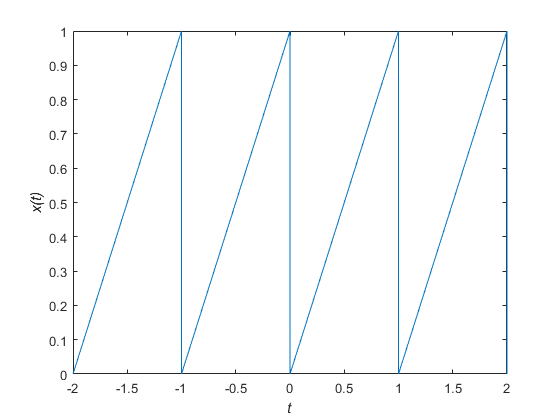

figure
xFunc = @(t)t-floor(t);
assert(all([xFunc(0.5)==0.5, xFunc(1.5)==0.5]));
fplot(xFunc, [-2, 2])
xlabel('{\it{t}}')
ylabel('{\it{x(t)}}')

By examining the plot, it is obvious that the function has a period of 1. Therefore, the lowest eigenvalue for the Fourier series is $\lambda {\;}_1 =1\cdot 2\pi =2\pi \;$, and the other eigenvalues are formed at integer multiples of that: $\lambda_n =n\cdot 2\pi$ for $n=1,2,3\ldotp \ldotp \ldotp$ This can be implemented in code as:

lambda_n = @(n) 2 .* pi .* n;
assert(lambda_n(2) == 4*pi);

Once the lambda values are known, the Fourier series coefficients can be calculated:


$$a_0 =\frac{1}{2}\int_0^2 x\left(t\right)\;\textrm{dt}$$



$$a_n =\frac{2}{2}\int_0^2 x\left(t\right)\;\cos \left(\lambda {\;}_n \;t\right)\;\textrm{dt}$$



$$b_n =\frac{2}{2}\int_0^2 x\left(t\right)\;\mathrm{sin}\left(\lambda {\;}_n \;t\right)\;\mathrm{dt}$$


This can be implemented as follows. Using Matlab's default numerical integration function will give better results than manually summing the components, with default absolute tolerances of 1e-10 and relative tolerances of 1e-6. This is sufficient for this application. A good way to confirm will be to look at the cosine coefficient values $a_n$: cosine values are used to fit even components of functions, but this function is purely odd, therefore they should all be zero.

a_0 = 0.5 * integral(xFunc, 0, 2);
a_n = @(n) integral(@(t) (xFunc(t) .* cos(lambda_n(n) .* t)), 0, 2, 'AbsTol', 1e-10, 'RelTol', 1e-6);
b_n = @(n) integral(@(t) (xFunc(t) .* sin(lambda_n(n) .* t)), 0, 2, 'AbsTol', 1e-10, 'RelTol', 1e-6);

The first 95 coefficients can be calculated:

n = 1:95;
a_nCoefs = zeros(size(n));
b_nCoefs = zeros(size(n));

for i = n
    a_nCoefs(i) = a_n(i);
    b_nCoefs(i) = b_n(i);
end

The phase angle and magnitude of the coefficients can be calculated:


$$\theta {\;}_{n\;} =\mathrm{atan2}\left(\frac{\;b_n }{a_n }\right)$$



$$|n|=\sqrt{\;a_n^2 +b_n^2 }$$


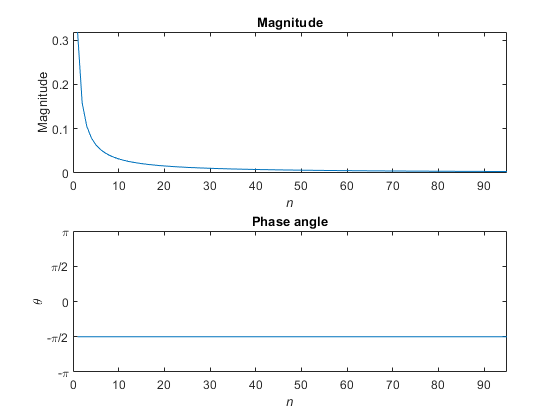

phase_n = atan2(b_nCoefs, a_nCoefs);
mag_n = abs(complex(a_nCoefs, b_nCoefs));
figure
subplot(2,1,1)
plot(n, mag_n)
title('Magnitude')
xlabel('\it{n}')
ylabel('Magnitude')
xlim([0 max(n)])
subplot(2,1,2)
plot(n, phase_n)
title('Phase angle')
xlabel('\it{n}')
ylabel('\theta')
xlim([0 max(n)]) 
ylim([-pi pi])
yticks([-pi -pi/2 0 pi/2 pi])
yticklabels(["-\pi" "-\pi/2" "0" "\pi/2" "\pi"])

Using those pre-calculated coefficients, the function to an arbitrary number of eigenvalues can be approximated:

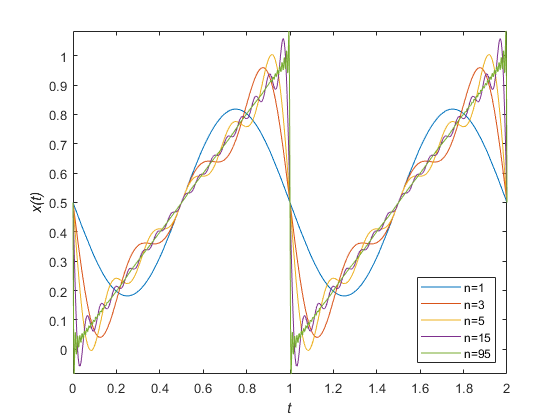

xFourier = @(n, x) (a_0 + sum(( cos(lambda_n(1:n) .* x') .* a_nCoefs(1:n) +  sin(lambda_n(1:n) .* x') .* b_nCoefs(1:n) )));

% Plot values
figure
fplot(@(x) xFourier(1,x), [0, 2]) % n=1
hold on
fplot(@(x) xFourier(3,x), [0, 2]) % n=3
fplot(@(x) xFourier(5,x), [0, 2]) % n=5
fplot(@(x) xFourier(15,x), [0, 2]) % n=15
fplot(@(x) xFourier(95,x), [0, 2]) % n=95
legend(["n=1" "n=3" "n=5" "n=15" "n=95"], 'location', 'southeast')
xlabel('\it{t}')
ylabel('\it{x(t)}')

It can be seen that the 